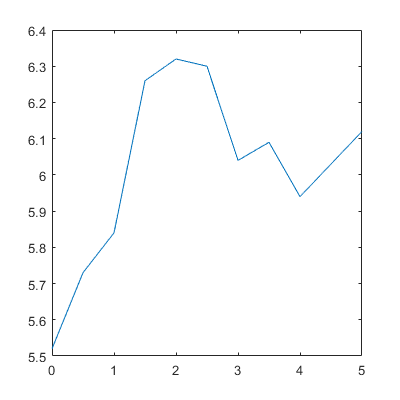

set(groot, 'DefaultFigurePosition', [200 200 400 400])

t = 0:0.5:5;
pH = [5.52, 5.73, 5.84, 6.26, 6.32, 6.30, 6.04, 6.09, 5.94, 6.03, 6.12];
plot(t, pH)

t = 0:0.5:5;
pH = [5.52, 5.73, 5.84, 6.26, 6.32, 6.30, 6.04, 6.09, 5.94, 6.03, 6.12];
plot(t, pH)

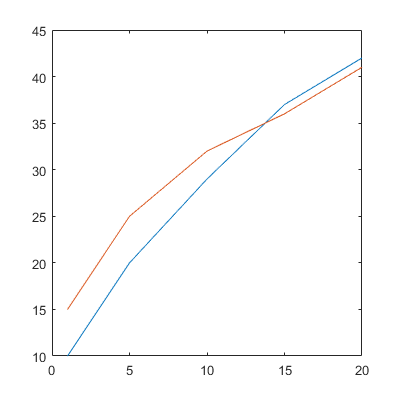

x = [1 5:5:20];
y1 = [10 20 29 37 42];
y2 = [15 25 32 36 41];
plot(x, y1, x, y2)

%hold on hold off


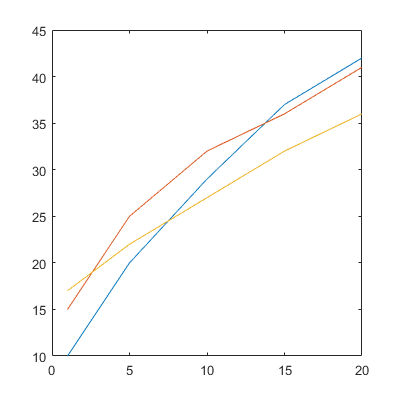

y3 = [17, 22, 27, 32, 36];
hold on
plot(x, y3)
hold off

subplot(2,2,1)
x = [1 5:5:20];
y1 = [10 20 29 37 42];
plot(x,y1)

subplot(2,2,2)
y2 = [15 25 32 36 41];
plot(x,y2)

subplot(2,2,3)
y3 = [17 22 27 32 36];
plot(x,y3)

subplot(2,2,4)
t = 0:pi/100:2*pi

t =          0    0.0314    0.0628    0.0942    0.1257    0.1571    0.1885    0.2199    0.2513    0.2827    0.3142    0.3456    0.3770    0.4084    0.4398    0.4712    0.5027    0.5341    0.5655    0.5969    0.6283    0.6597    0.6912    0.7226    0.7540    0.7854    0.8168    0.8482    0.8796    0.9111    0.9425    0.9739    1.0053    1.0367    1.0681    1.0996    1.1310    1.1624    1.1938    1.2252    1.2566    1.2881    1.3195    1.3509    1.3823    1.4137    1.4451    1.4765    1.5080    1.5394


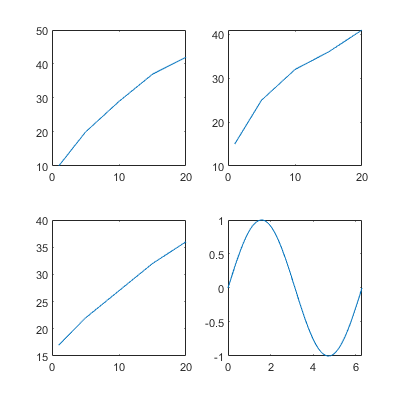

plot(t,sin(t))

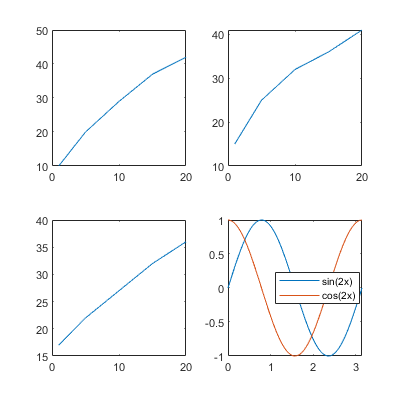

x = 0:pi/100:pi;
y1 = sin(2*x);
y2 = cos(2*x);
plot(x,y1,x,y2)
legend('sin(2x)', 'cos(2x)', 'Location', 'best')
axis tight

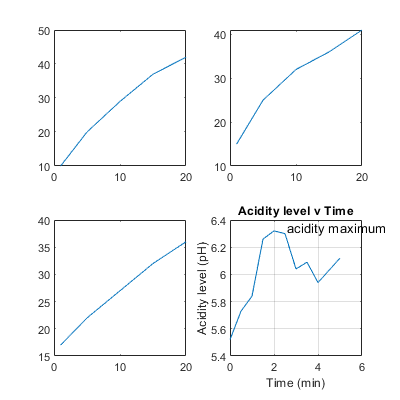

t = 0:0.5:5;
pH = [5.52, 5.73, 5.84, 6.26, 6.32, 6.30, 6.04, 6.09, 5.94, 6.03, 6.12];
plot(t, pH)
title('Acidity level v Time')
xlabel('Time (min)')
ylabel('Acidity level (pH)')
text(2.6, 6.35, 'acidity maximum')
grid

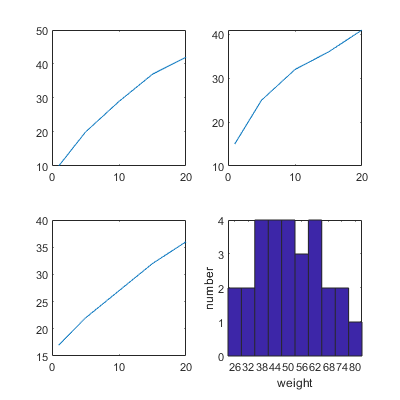

y = [57,48,42,44,50,38,57,62,63,39,32,83,63,47,48,54,41,36,69,75,53,71,33,23,42,29,75,60];
hist(y)
xlabel('weight')
ylabel('number')

n = hist(y);
n

n =      2     2     4     4     4     3     4     2     2     1


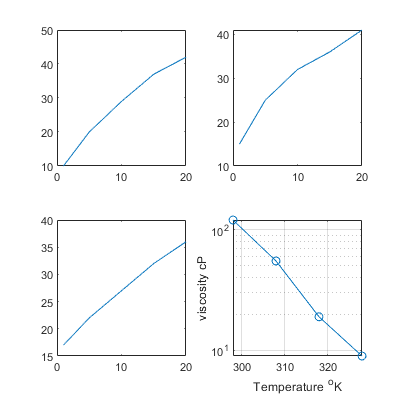

vis = [120 55 19 9];
T = [298 308 318 328];
semilogy(T, vis, '-o')
xlabel('Temperature ^oK')
ylabel('viscosity cP')
axis tight, grid

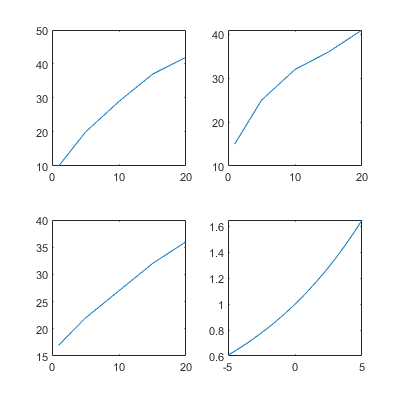

fplot(@(x)exp(.1*x))

# Simple equilibriuim reaction

Ao = 0.25;
Bo = 0.1;
kf = 2;
kb = 1;

t = 0:0.1;1;

r1 = (1/(kf+kb))*(kb+kf*exp(-(kf+kb)*t));
r2 = (kf/(kf+kb))*(1-exp(-(kf+kb)*t));

A = Ao*r1 + Bo*r2;
B = Ao*r2 + Bo*r1;

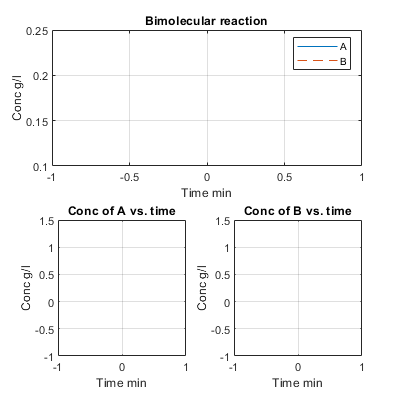

subplot(2,2, [1,2])
plot(t,A,t,B,'--')
xlabel('Time min')
ylabel('Conc g/l')
title('Bimolecular reaction')
legend('A', 'B')
grid

subplot(2,2,3)
plot(t,A)
xlabel('Time min')
ylabel('Conc g/l')
title('Conc of A vs. time')
grid

subplot(2,2,4)
plot(t,B)
xlabel('Time min')
ylabel('Conc g/l')
title('Conc of B vs. time')
grid

%%bacterial growth curve


N0 = 150;
r = 0.5;
x = 0:8;               % no of generations
t = x/2;               % elased time
N = round(N0*(1+r).^x)

N =          150         225         338         506         759        1139        1709        2563        3844


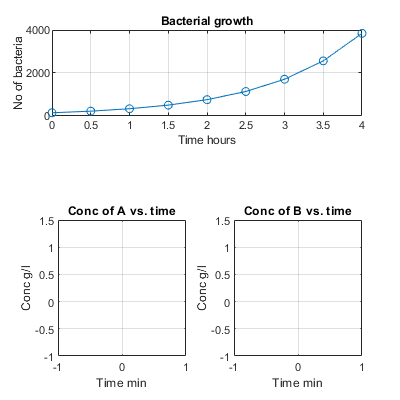

subplot(3,1,1)
plot(t,N,'-o')
title('Bacterial growth')
xlabel('Time hours')
ylabel('No of bacteria')
grid

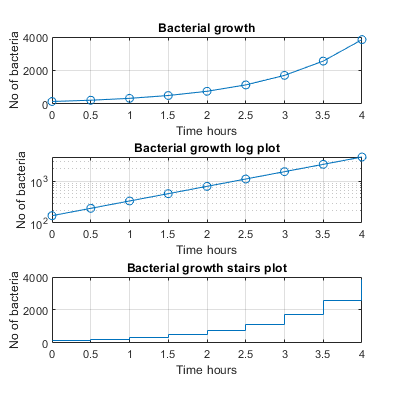


subplot(3,1,2)
semilogy(t,N,'-o')
title('Bacterial growth log plot')
xlabel('Time hours')
ylabel('No of bacteria')
grid

subplot(3,1,3)
stairs(t,N)
title('Bacterial growth stairs plot')
xlabel('Time hours')
ylabel('No of bacteria')
grid

# Specific volume of air

T = [273.15:20:373.15];
v_exp = [0.7734 0.8288 0.8873 0.9372 1 1.0571];
p = 101.3;
R = 0.286;
v_theory =  R*T/p;

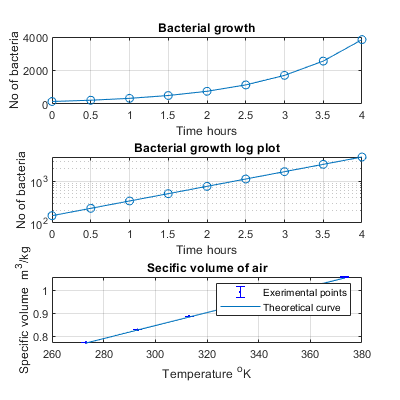

v_error = 0.001*v_theory;
errorbar(T,v_exp,v_error, '.b');
hold on
plot(T, v_theory)
grid
xlabel('Temperature ^oK')
ylabel('Specific volume  m^3/kg')
title('Secific volume of air')
legend('Exerimental points', 'Theoretical curve')
hold off

# Partial ressure first order reaction

P0 = 55;
Ea = 77e3;
A = 1e14;
R = 8.314;
T = 293.15:303;
%A0 = 0.25;
t = 1:0.25:4

t =     1.0000    1.2500    1.5000    1.7500    2.0000    2.2500    2.5000    2.7500    3.0000    3.2500    3.5000    3.7500    4.0000


[X,Y] = meshgrid(t,T);

k = A*exp(-Ea./(R*Y));
Z = P0*exp(-k.*X)  %Pa = Z

Z =     8.2053    5.0995    3.1693    1.9697    1.2241    0.7608    0.4728    0.2939    0.1826    0.1135    0.0705    0.0438    0.0272
    6.6132    3.8942    2.2932    1.3503    0.7952    0.4682    0.2757    0.1624    0.0956    0.0563    0.0332    0.0195    0.0115
    5.2101    2.8905    1.6036    0.8896    0.4935    0.2738    0.1519    0.0843    0.0468    0.0259    0.0144    0.0080    0.0044
    4.0035    2.0795    1.0802    0.5611    0.2914    0.1514    0.0786    0.0408    0.0212    0.0110    0.0057    0.0030    0.0015
    2.9934    1.4458    0.6983    0.3373    0.1629    0.0787    0.0380    0.0184    0.0089    0.0043    0.0021    0.0010    0.0005
    2.1719    0.9682    0.4316    0.1924    0.0858    0.0382    0.0170    0.0076    0.0034    0.0015    0.0007    0.0003    0.0001
    1.5250    0.6223    0.2539    0.1036    0.0423    0.0173    0.0070    0.0029    0.0012    0.0005    0.0002    0.0001    0.0000
    1.0330    0.3824    0.1416    0.0524    0.0194    0.0072    0.0027    0.001

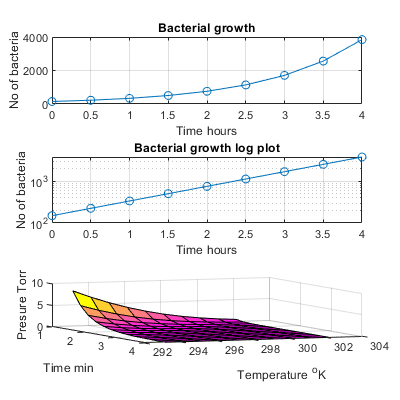

surf(X,Y,Z)
grid on
xlabel('Time min')
ylabel('Temperature ^oK')
zlabel('Presure Torr')
view(67,22)
colormap spring

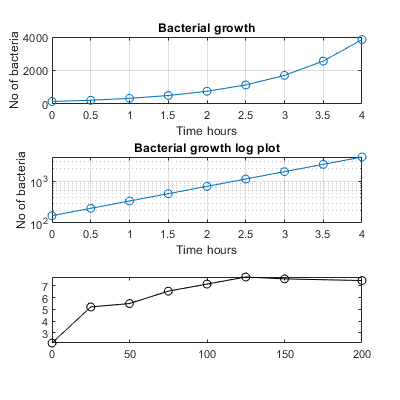

%5 aerobic biomass mass/time
m = [2.15 5.21 5.5 6.55 7.15 7.75 7.59 7.45];
t = [0 25 50 75 100 125 150 200];
plot(t,m,'-ok')

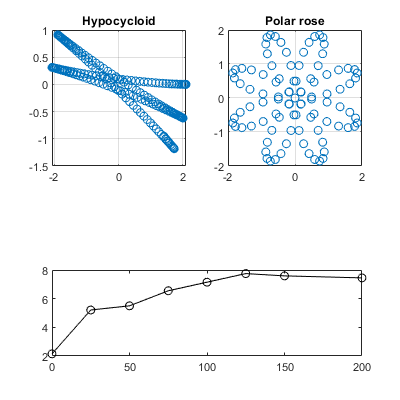

%6 geometrical figures
p1 = 0:4*pi/200:4*pi;
x1 = 1.1*cos(p1) + cos(1.1*p1);
y1 = 1.1*sin(p1) - sin(1.1*p1);
subplot(2,2,1)
plot(x1,y1,'o')
grid
title('Hypocycloid')

p2 = 0:2*pi/100:2*pi;
x2 = 2.*sin(4*p2).*cos(p2);
y2 = 2.*sin(4*p2).*sin(p2);
subplot(2,2,2)
plot(x2,y2, 'o')
grid
title('Polar rose')

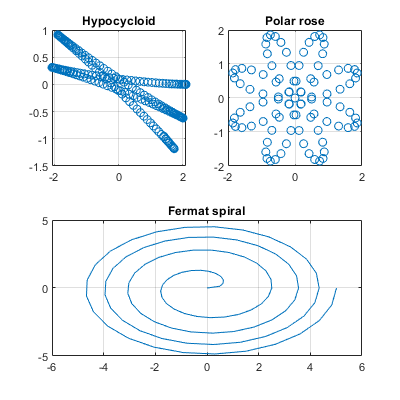


p3 = 0:8*pi/100:8*pi;
x3 = sqrt(p3).*cos(p3);
y3 = sqrt(p3).*sin(p3);
subplot(2,2,[3,4])
plot(x3,y3)
grid
title('Fermat spiral')

t = 0:1:23

t =      0     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23


x = (((2.10)^(-5))*(exp(-0.0256*t)-1))./(0.002*(exp(0.0256*t)-1))

x =        NaN  -11.9332  -11.6316  -11.3376  -11.0510  -10.7717  -10.4994  -10.2341   -9.9754   -9.7233   -9.4775   -9.2380   -9.0045   -8.7769   -8.5550   -8.3388   -8.1281   -7.9226   -7.7224   -7.5272   -7.3369   -7.1515   -6.9707   -6.7946


v = 319.45*(0.01-x).*(0.002-x)

v = 	1.0e+04 *

       NaN    4.5536    4.3264    4.1106    3.9055    3.7107    3.5256    3.3497    3.1826    3.0239    2.8730    2.7297    2.5936    2.4642    2.3413    2.2245    2.1136    2.0082    1.9080    1.8128    1.7224    1.6365    1.5549    1.4774


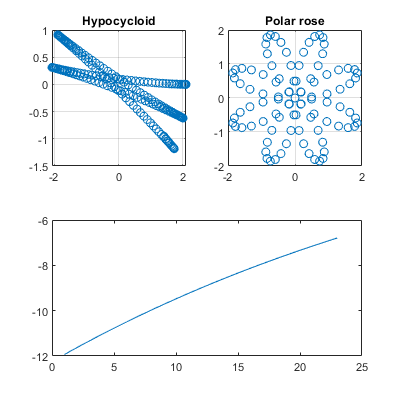

plot(t,x)

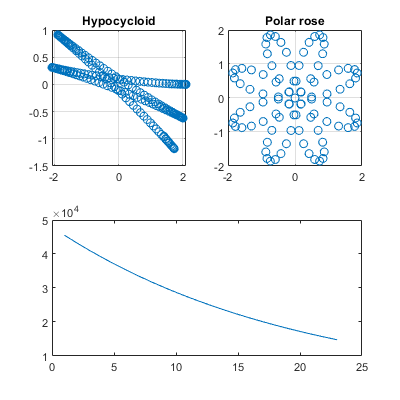

plot(t,v)

%8 kinematic viscosity v temperature
v_obs = [120.14 81.78 58.48 43.30];
temp = 298.15:10:328.15;
A = 0.00142;
B = 3382;

v_exp = A*exp(B./temp)

v_exp =   119.8433   82.9366   58.7392   42.4855


v_err = abs(v_exp-v_obs)*100./v_exp

v_err =     0.2476    1.3945    0.4413    1.9170


% error = +/- 0.5 uncertainity 

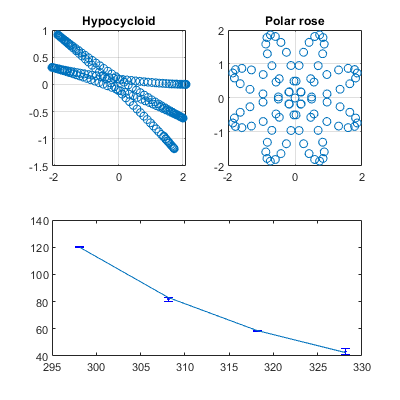

errorbar(temp, v_obs, v_err, '.b') 
hold on
plot(temp, v_exp)

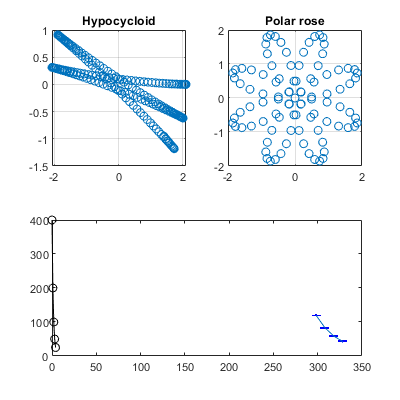

%radioactive decay

reading = [400 200 100 50 25];
time = [0 1 2 3 4];

semilogy(time, reading, '-ok')

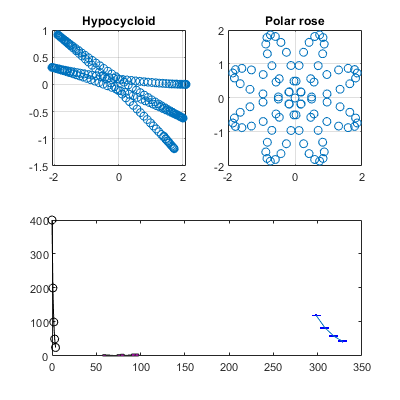

%11 weights
w = [65,80,95,93,67,81,90,93,92,83,86,83,90,94,93,96,96,98,96,59,75,81,65,88,81,65,88,81,60,57,61,68,77,75,76,70];
hist(w)

n = hist(w)

n =      4     3     2     1     4     5     2     3     6     6


average = mean(w)

average = 80.5000

stddev = std(w)

stddev = 12.4614

%bacteria doubling time

N0 = 100;
t = 0:0.5:3;
N = N0*(2.^t)

N =   100.0000  141.4214  200.0000  282.8427  400.0000  565.6854  800.0000


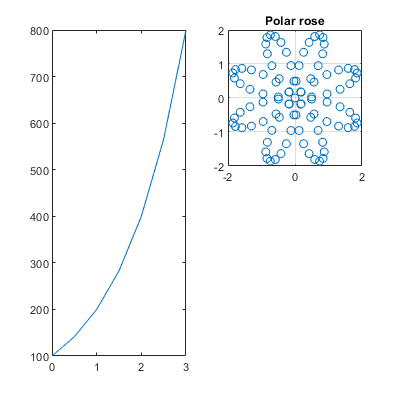


subplot(1,2,1)
plot(t,N)

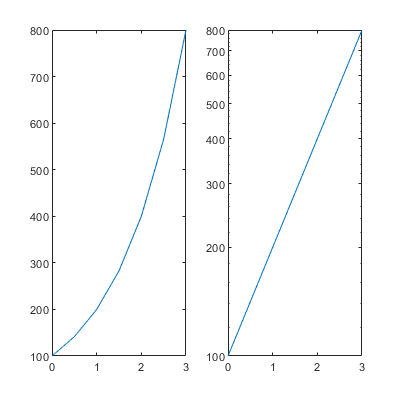

subplot(1,2,2)
semilogy(t,N)

% M1V1 = M2V2
m1 = 0.1:0.1:1.0

m1 =     0.1000    0.2000    0.3000    0.4000    0.5000    0.6000    0.7000    0.8000    0.9000    1.0000


m2 = 0.1:0.2:2.0

m2 =     0.1000    0.3000    0.5000    0.7000    0.9000    1.1000    1.3000    1.5000    1.7000    1.9000


v1 = 0.1:0.1:0.9

v1 =     0.1000    0.2000    0.3000    0.4000    0.5000    0.6000    0.7000    0.8000    0.9000


[X,Y] = meshgrid(m1,v1)

X =     0.1000    0.2000    0.3000    0.4000    0.5000    0.6000    0.7000    0.8000    0.9000    1.0000
    0.1000    0.2000    0.3000    0.4000    0.5000    0.6000    0.7000    0.8000    0.9000    1.0000
    0.1000    0.2000    0.3000    0.4000    0.5000    0.6000    0.7000    0.8000    0.9000    1.0000
    0.1000    0.2000    0.3000    0.4000    0.5000    0.6000    0.7000    0.8000    0.9000    1.0000
    0.1000    0.2000    0.3000    0.4000    0.5000    0.6000    0.7000    0.8000    0.9000    1.0000
    0.1000    0.2000    0.3000    0.4000    0.5000    0.6000    0.7000    0.8000    0.9000    1.0000
    0.1000    0.2000    0.3000    0.4000    0.5000    0.6000    0.7000    0.8000    0.9000    1.0000
    0.1000    0.2000    0.3000    0.4000    0.5000    0.6000    0.7000    0.8000    0.9000    1.0000
    0.1000    0.2000    0.3000    0.4000    0.5000    0.6000    0.7000    0.8000    0.9000    1.0000


Y =     0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000
    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000
    0.3000    0.3000    0.3000    0.3000    0.3000    0.3000    0.3000    0.3000    0.3000    0.3000
    0.4000    0.4000    0.4000    0.4000    0.4000    0.4000    0.4000    0.4000    0.4000    0.4000
    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000
    0.6000    0.6000    0.6000    0.6000    0.6000    0.6000    0.6000    0.6000    0.6000    0.6000
    0.7000    0.7000    0.7000    0.7000    0.7000    0.7000    0.7000    0.7000    0.7000    0.7000
    0.8000    0.8000    0.8000    0.8000    0.8000    0.8000    0.8000    0.8000    0.8000    0.8000
    0.9000    0.9000    0.9000    0.9000    0.9000    0.9000    0.9000    0.9000    0.9000    0.9000


V2 = X.*Y./m2

V2 =     0.1000    0.0667    0.0600    0.0571    0.0556    0.0545    0.0538    0.0533    0.0529    0.0526
    0.2000    0.1333    0.1200    0.1143    0.1111    0.1091    0.1077    0.1067    0.1059    0.1053
    0.3000    0.2000    0.1800    0.1714    0.1667    0.1636    0.1615    0.1600    0.1588    0.1579
    0.4000    0.2667    0.2400    0.2286    0.2222    0.2182    0.2154    0.2133    0.2118    0.2105
    0.5000    0.3333    0.3000    0.2857    0.2778    0.2727    0.2692    0.2667    0.2647    0.2632
    0.6000    0.4000    0.3600    0.3429    0.3333    0.3273    0.3231    0.3200    0.3176    0.3158
    0.7000    0.4667    0.4200    0.4000    0.3889    0.3818    0.3769    0.3733    0.3706    0.3684
    0.8000    0.5333    0.4800    0.4571    0.4444    0.4364    0.4308    0.4267    0.4235    0.4211
    0.9000    0.6000    0.5400    0.5143    0.5000    0.4909    0.4846    0.4800    0.4765    0.4737


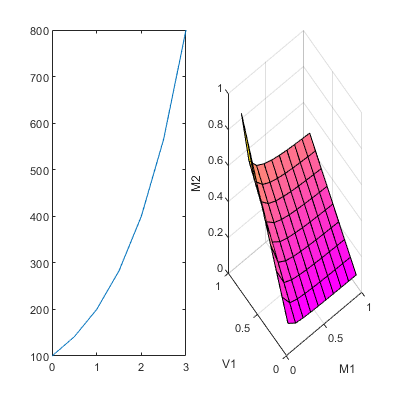

Z = V2;
surf(X,Y,Z)
xlabel('M1'), ylabel('V1'), zlabel('M2')

%view(-135,35)
